NAME = '2024-11-05'; %Название папки с данными
NEW = 0; %Обновить данные из текстовых: 0-нет, 1-МГТУ, 2-РНЦХ
CYCLE_KEY = 1; %Обновить данные циклов
CYCLE_FIND = 'REO1'; %Алгоритм определения циклов по ECGP, ECGN, REO1, REO2
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_base2 = zeros(N,1)

means_base2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


means_base1 = zeros(N,1)

means_base1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


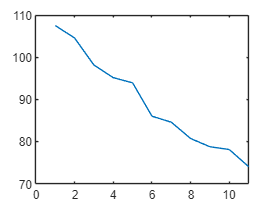

for i = 1:N
    if i == N
        Data_base2 = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1 = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1);
        means_base2(i) = mean(Data_base2);
    else
        Data_base2 = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1 = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1);
        means_base2(i) = mean(Data_base2);
    end
end
plot(means_base1)

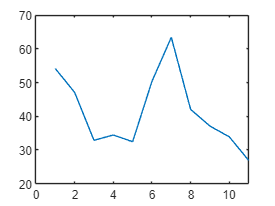

plot(means_base2)

%Data_test_base2_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"BASE2"));
%Data_test_date_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"DATE"));



%plot(Data_test_date_1,Data_test_base2_1)
%plot(Data_test_date_2,Data_test_base2_2)
mean(Data_test_base2_1)

Unrecognized function or variable 'Data_test_base2_1'.

mean(Data_test_base2_2)

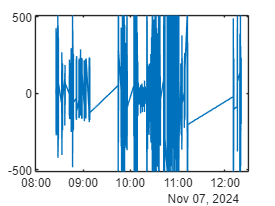

plot(DATA.DATE,DATA.RHEO1)

%Руки: 79.9 - Арина, 175.7 - Паша Ч, 120.4  - Паша Р., 132.7 - Дима
%Голова: 81.8 - Арина, 67.8 - Паша Ч, 86.1 - Паша Р., 90.7 - Дима

NAME = '2024-11-07'; %Название папки с данными
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_base1 = zeros(N,1)

means_base1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


means_base2 = zeros(N,1)

means_base2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


std_dev_b1 = zeros(N,1)

std_dev_b1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


std_dev_b2 = zeros(N,1)

std_dev_b2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 1:N
    if i == N
        Data_base2{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        std_dev_b1(i) = std(Data_base1{i});
        means_base2(i) = mean(Data_base2{i});
        std_dev_b2(i) = std(Data_base2{i});
    else
        Data_base2{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE2"));
        Data_base1{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"BASE1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        means_base2(i) = mean(Data_base2{i});
        std_dev_b1(i) = std(Data_base1{i});
        std_dev_b2(i) = std(Data_base2{i});
    end
end

x=1:11

x =      1     2     3     4     5     6     7     8     9    10    11


data = [means_base1,means_base2];
std_data = [std_dev_b1,std_dev_b2];
figure

b = bar(x,data)

b =   1×2 Bar array:

    Bar    Bar


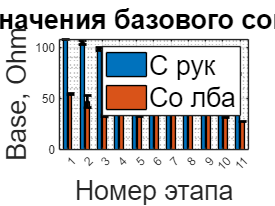

hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Средние значения базового сопротивления",'FontSize', 20)

lgd = legend(["С рук","Со лба"]);
fontsize(lgd,20,'points')
ylabel('Base, Ohm','FontSize', 20) 
xlabel('Номер этапа','FontSize', 20)
grid on
grid minor
hold off

NAME = '2024-11-07'; %Название папки с данными
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(TT.DATE);
means_base1 = zeros(N,1)

means_base1 =      0
     0
     0


means_base2 = zeros(N,1)

means_base2 =      0
     0
     0


std_dev_b1 = zeros(N,1)

std_dev_b1 =      0
     0
     0


std_dev_b2 = zeros(N,1)

std_dev_b2 =      0
     0
     0


for i = 1:N
    if i == N
        Data_base2{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"RHEO2"));
        Data_base1{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"RHEO1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        Data_date{i} = table2array(DATA(find((DATA.DATE > TT.DATE(i))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        std_dev_b1(i) = std(Data_base1{i});
        means_base2(i) = mean(Data_base2{i});
        std_dev_b2(i) = std(Data_base2{i});
    else
        Data_base2{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"RHEO2"));
        Data_base1{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"RHEO1"));
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));
        Data_date{i} = table2array(DATA(find(DATA.DATE < TT.DATE(i+1) & (DATA.DATE > TT.DATE(i))),"DATE"));
        means_base1(i) = mean(Data_base1{i});
        means_base2(i) = mean(Data_base2{i});
        std_dev_b1(i) = std(Data_base1{i});
        std_dev_b2(i) = std(Data_base2{i});
    end
end

x=1:3

x =      1     2     3


data = [means_base1,means_base2];
std_data = [std_dev_b1,std_dev_b2];
figure

b = bar(x,data)

b =   1×2 Bar array:

    Bar    Bar


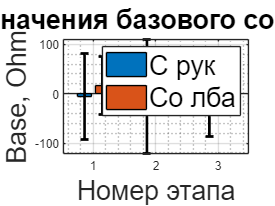

hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off
title("Средние значения базового сопротивления",'FontSize', 20)

lgd = legend(["С рук","Со лба"]);
fontsize(lgd,20,'points')
ylabel('Base, Ohm','FontSize', 20) 
xlabel('Номер этапа','FontSize', 20)
grid on
grid minor
hold off

var1=[105.145,107.084,113.908,84.5684,101.587];
dvar1 = std(var1)

dvar1 = 10.9604

NAME = '2024-11-21'; %Название папки с данными
NEW = 0; %Обновить данные из текстовых: 0-нет, 1-МГТУ, 2-РНЦХ
CYCLE_KEY = 1; %Обновить данные циклов
CYCLE_FIND = 'REO1'; %Алгоритм определения циклов по ECGP, ECGN, REO1, REO2
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(CYCLE_DATA);
amps_rheo2 = zeros(N,1)

amps_rheo2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


amps_rheo1 = zeros(N,1)

amps_rheo1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


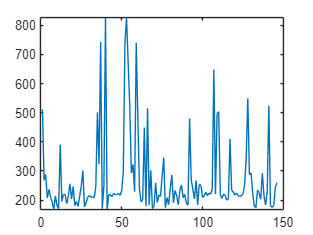

for i = 1:N
    amps_rheo2(i) = max(CYCLE_BR{i}.RHEO2)-min(CYCLE_BR{i}.RHEO2);
    amps_rheo1(i) = max(CYCLE_BR{i}.RHEO1)-min(CYCLE_BR{i}.RHEO1);
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));   
end
plot(amps_rheo1)

amps_rheo11 = amps_rheo1(amps_rheo1<300);
%amps_rheo22 = amps_rheo2(4226:(4226+180));
mean(amps_rheo11)

ans = 217.9038

std(amps_rheo11)

ans = 30.8410

mean(amps_rheo2)

ans = 51.3155

std(amps_rheo2)

ans = 14.1373

%Data_test_base2_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"BASE2"));
%Data_test_date_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"DATE"));

NAME = '2024-11-07'; %Название папки с данными
NEW = 0; %Обновить данные из текстовых: 0-нет, 1-МГТУ, 2-РНЦХ
CYCLE_KEY = 1; %Обновить данные циклов
CYCLE_FIND = 'REO1'; %Алгоритм определения циклов по ECGP, ECGN, REO1, REO2
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(CYCLE_BR);
amps_rheo2 = zeros(N,1)

amps_rheo2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


amps_rheo1 = zeros(N,1)

amps_rheo1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


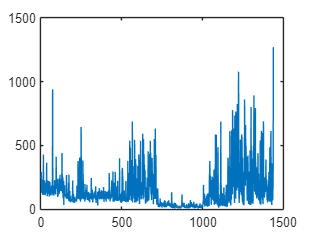

for i = 1:N
    amps_rheo2(i) = max(CYCLE_BR{i}.RHEO2)-min(CYCLE_BR{i}.RHEO2);
    amps_rheo1(i) = max(CYCLE_BR{i}.RHEO1)-min(CYCLE_BR{i}.RHEO1);
        %Data_test_date_1 = table2array(DATA(find(DATA.DATE < TT.DATE(2) & (DATA.DATE > TT.DATE(1))),"DATE"));   
end
plot(amps_rheo1)

amps_rheo11 = amps_rheo1(amps_rheo1<300);
%amps_rheo22 = amps_rheo2(4226:(4226+180));
mean(amps_rheo11)

ans = 106.7606

std(amps_rheo11)

ans = 69.7051

mean(amps_rheo2)

ans = 38.5065

std(amps_rheo2)

ans = 42.4705

%Data_test_base2_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"BASE2"));
%Data_test_date_2 = table2array(DATA(find(DATA.DATE < TT.DATE(3) & (DATA.DATE > TT.DATE(2))),"DATE"));

NAME = '2024-11-07'; %Название папки с данными
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(CYCLE_BR);
M = length(TT.DATE);
M = 5;
means_rheo1 = zeros(M,1)

means_rheo1 =      0
     0
     0
     0
     0


means_rheo2 = zeros(M,1)

means_rheo2 =      0
     0
     0
     0
     0


std_dev_r1 = zeros(M,1)

std_dev_r1 =      0
     0
     0
     0
     0


std_dev_r2 = zeros(M,1)

std_dev_r2 =      0
     0
     0
     0
     0


k=1;

for i = 1:M
    for j = 1:N
        if (i == M)
            if (CYCLE_BR{j}.NAME > TT.DATE(i))
            sum_rheo1{k} = max(CYCLE_BR{j}.RHEO1)-min(CYCLE_BR{j}.RHEO1);
            sum_rheo2{k} = max(CYCLE_BR{j}.RHEO2)-min(CYCLE_BR{j}.RHEO2);
            k = k+1;
            end
        elseif ((CYCLE_BR{j}.NAME < TT.DATE(i+1)) && (CYCLE_BR{j}.NAME > TT.DATE(i)))
            sum_rheo1{k} = max(CYCLE_BR{j}.RHEO1)-min(CYCLE_BR{j}.RHEO1);
            sum_rheo2{k} = max(CYCLE_BR{j}.RHEO2)-min(CYCLE_BR{j}.RHEO2);
            k = k+1;
            
        end
    end
    means_rheo1(i) = mean(cell2mat(sum_rheo1));
    std_dev_r1(i) = std(cell2mat(sum_rheo1));
    means_rheo2(i) = mean(cell2mat(sum_rheo2));
    std_dev_r2(i) = std(cell2mat(sum_rheo2));
    clear sum_rheo1 sum_rheo2;
    k = 1;
end

x=1:5

x =      1     2     3     4     5


data = [means_rheo1,means_rheo2];
std_data = [std_dev_r1,std_dev_r2];
figure

b = bar(x,data)

b =   1×2 Bar array:

    Bar    Bar


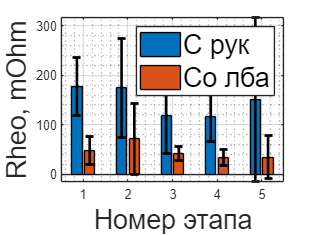

hold on
for k = 1:numel(b)                                                      % Recent MATLAB Versions
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    errorbar(xtips,ytips,std_data(:,k), '.k', 'MarkerSize',1,'LineWidth',2)
end
hold off


lgd = legend(["С рук","Со лба"]);
fontsize(lgd,20,'points')
ylabel('Rheo, mOhm','FontSize', 20) 
xlabel('Номер этапа','FontSize', 20)
grid on
grid minor
hold off

%% Обработка последних экспериментов. Вычитание с башки %%

NAME = '2024-12-19'; %Название папки с данными
load(strcat('OUT/',NAME,'/DATA.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(CYCLE_BR);
M = length(TT.DATE);
M = 5;
means_rheo1 = zeros(M,1)

means_rheo1 =      0
     0
     0
     0
     0


means_rheo2 = zeros(M,1)

means_rheo2 =      0
     0
     0
     0
     0


std_dev_r1 = zeros(M,1)

std_dev_r1 =      0
     0
     0
     0
     0


std_dev_r2 = zeros(M,1)

std_dev_r2 =      0
     0
     0
     0
     0


k=1;

for i = 1:M
    for j = 1:N
        if (i == M)
            if (CYCLE_BR{j}.NAME > TT.DATE(i))
            sum_rheo1{k} = max(CYCLE_BR{j}.RHEO1)-min(CYCLE_BR{j}.RHEO1);
            sum_rheo2{k} = max(CYCLE_BR{j}.RHEO2)-min(CYCLE_BR{j}.RHEO2);
            k = k+1;
            end
        elseif ((CYCLE_BR{j}.NAME < TT.DATE(i+1)) && (CYCLE_BR{j}.NAME > TT.DATE(i)))
            sum_rheo1{k} = max(CYCLE_BR{j}.RHEO1)-min(CYCLE_BR{j}.RHEO1);
            sum_rheo2{k} = max(CYCLE_BR{j}.RHEO2)-min(CYCLE_BR{j}.RHEO2);
            k = k+1;
            
        end
    end
    means_rheo1(i) = mean(cell2mat(sum_rheo1));
    std_dev_r1(i) = std(cell2mat(sum_rheo1));
    means_rheo2(i) = mean(cell2mat(sum_rheo2));
    std_dev_r2(i) = std(cell2mat(sum_rheo2));
    clear sum_rheo1 sum_rheo2;
    k = 1;
end

NAME = '2024-12-19'; %Название папки с данными
load(strcat('OUT/',NAME,'/CYCLE.mat'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
N = length(CYCLE);

DATE_brain = [];
ECG_brain = [];
RHEO1_brain = [];
BASE1_brain = [];
RHEO2_brain_amp = [];
BASE2_brain = [];
for i=1:N
    if (CYCLE{i}.NAME < TT.DATE(2) && ((max(CYCLE{i}.RHEO2) - min(CYCLE{i}.RHEO2))<50))
    DATE_brain = [DATE_brain; CYCLE{i}.NAME+seconds(CYCLE{i}.TIME)];
    ECG_brain = [ECG_brain; CYCLE{i}.ECG];
    RHEO1_brain = [RHEO1_brain; CYCLE{i}.RHEO1];
    BASE1_brain = [BASE1_brain; CYCLE{i}.BASE1];
    RHEO2_brain_amp = [RHEO2_brain_amp; max(CYCLE{i}.RHEO2)-min(CYCLE{i}.RHEO2)];
    BASE2_brain = [BASE2_brain; CYCLE{i}.BASE2];
    end
end

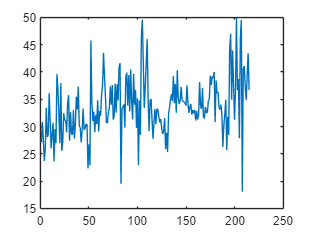

plot(RHEO2_brain_amp)

mean(RHEO2_brain_amp)

ans = 33.6150

std(RHEO2_brain_amp)

ans = 5.2211

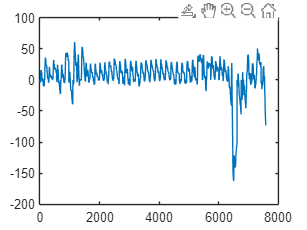

plot(RHEO2_brain)

DATE_fh = [];
ECG_fh = [];
RHEO1_fh = [];
BASE1_fh = [];
RHEO2_fh = [];
BASE2_fh = [];
for i=1:N
    if ((CYCLE{i}.NAME > TT.DATE(2)) && (CYCLE{i}.NAME < TT.DATE(3)))
    DATE_fh = [DATE_fh; CYCLE{i}.NAME+seconds(CYCLE{i}.TIME)];
    ECG_fh = [ECG_fh; CYCLE{i}.ECG];
    RHEO1_fh = [RHEO1_fh; CYCLE{i}.RHEO1];
    BASE1_fh = [BASE1_fh; CYCLE{i}.BASE1];
    RHEO2_fh = [RHEO2_fh; CYCLE{i}.RHEO2];
    BASE2_fh = [BASE2_fh; CYCLE{i}.BASE2];
    end
end

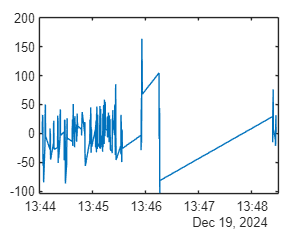


plot(DATE_fh,RHEO2_fh-RHEO2_brain(1:length(RHEO2_fh)))

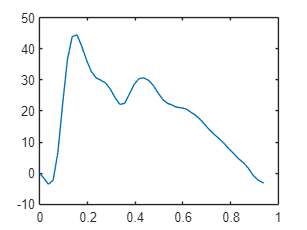

n1 = 72;
n2 = 12;
plot(CYCLE{n1}.TIME,CYCLE{n1}.RHEO2)

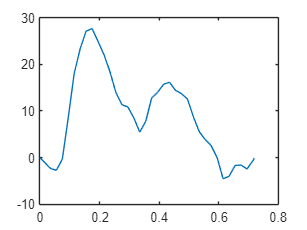

plot(CYCLE{n2}.TIME,CYCLE{n2}.RHEO2)

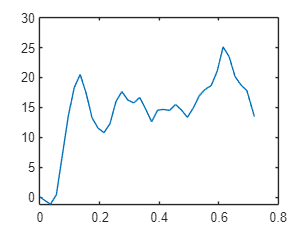

plot(CYCLE{n2}.TIME,CYCLE{n1}.RHEO2(1:length(CYCLE{n2}.RHEO2))-CYCLE{n2}.RHEO2)

length(CYCLE{72}.RHEO2)

ans = 189

length(CYCLE{10}.RHEO2)

ans = 129